# Изменение частоты дискретизации в 4/5 раза без использования фильтра

#### Исходный сигнал - синусоида частотой 1000 Гц с частотой дискретизации fs1 = 8000 Гц:

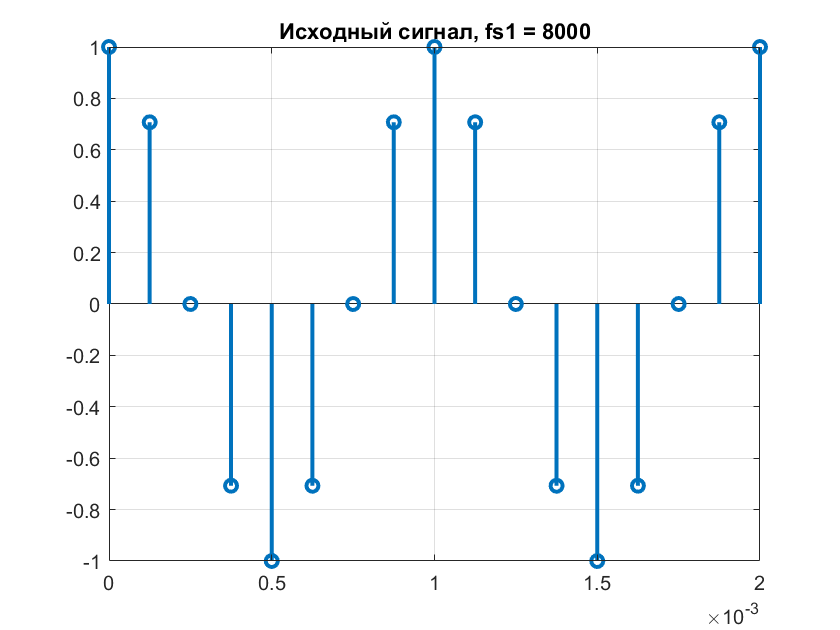

up = 4;
down = 5;
fs1 = 8000;
fs2 = fs1*up;
fs3 = fs2/down;
f0 = 1000;
t1 = 0:1/fs1:1;
t2 = 0:1/fs2:1;
t3 = 0:1/fs3:1;
x1 = cos(2*pi*f0*t1);
stem(t1,x1,'LineWidth',2);
title('Исходный сигнал, fs1 = 8000');
xlim([0 2e-3]); grid on;

sound(x1,fs1);

#### Повышение частоты дискретизации в 4 раза дополнением нулями:

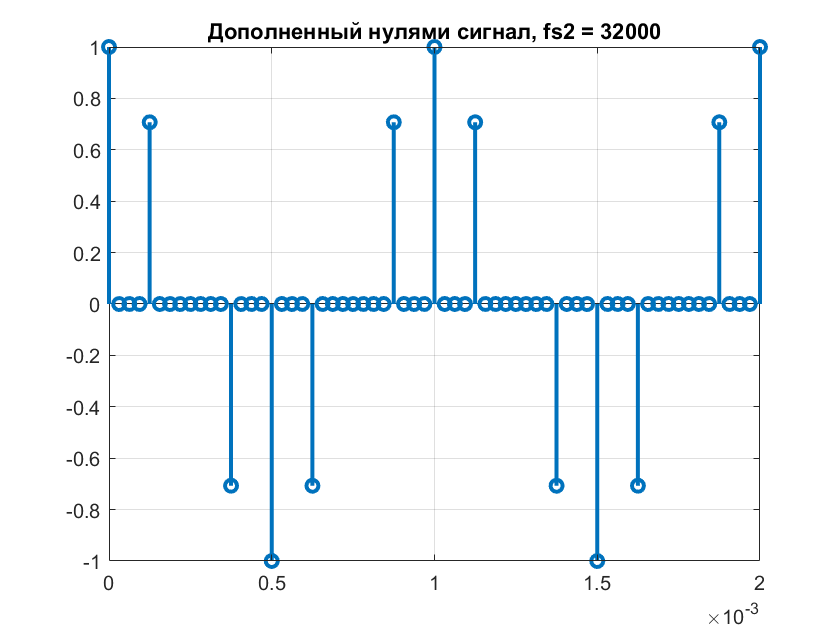

x2 = upsample(x1,up);
x2 = x2(1:end-(up-1));
stem(t2,x2,'LineWidth',2);
xlim([0 2e-3]); grid on;
title('Дополненный нулями сигнал, fs2 = 32000');

sound(x2,fs2);

#### Понижение частоты дискретизации в 5 раз:

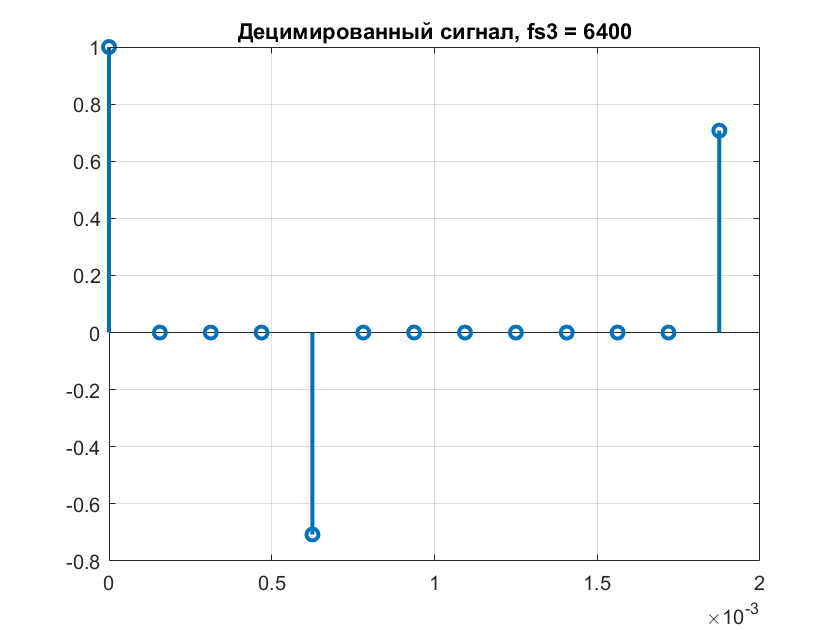

x3 = downsample(x2,down);
stem(t3,x3,'LineWidth',2);
title('Децимированный сигнал, fs3 = 6400');
xlim([0 2e-3]); grid on;

sound(x3,fs3);

#### Спектры сигналов на разных стадиях обработки:

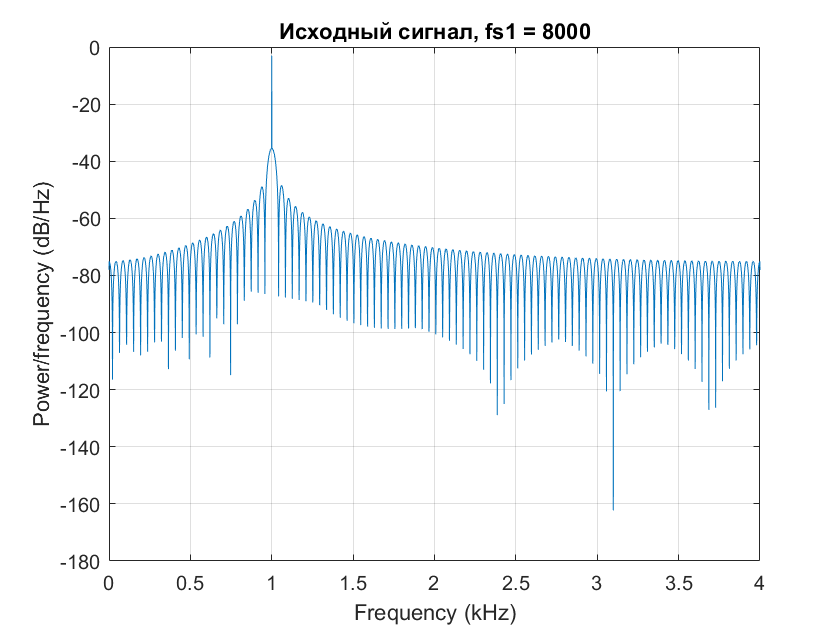

periodogram(x1,[],[],fs1);
title('Исходный сигнал, fs1 = 8000');

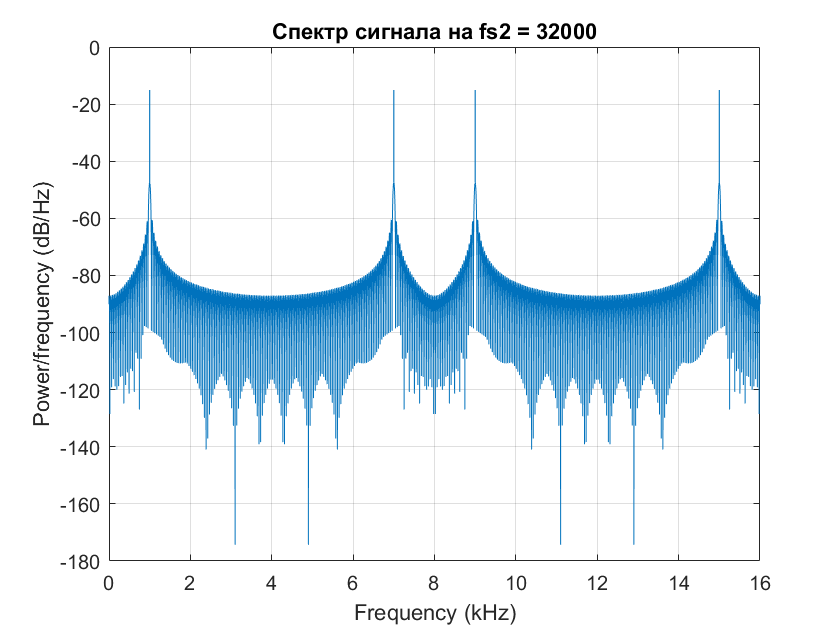

periodogram(x2,[],[],fs2);
title('Cпектр сигнала на fs2 = 32000');

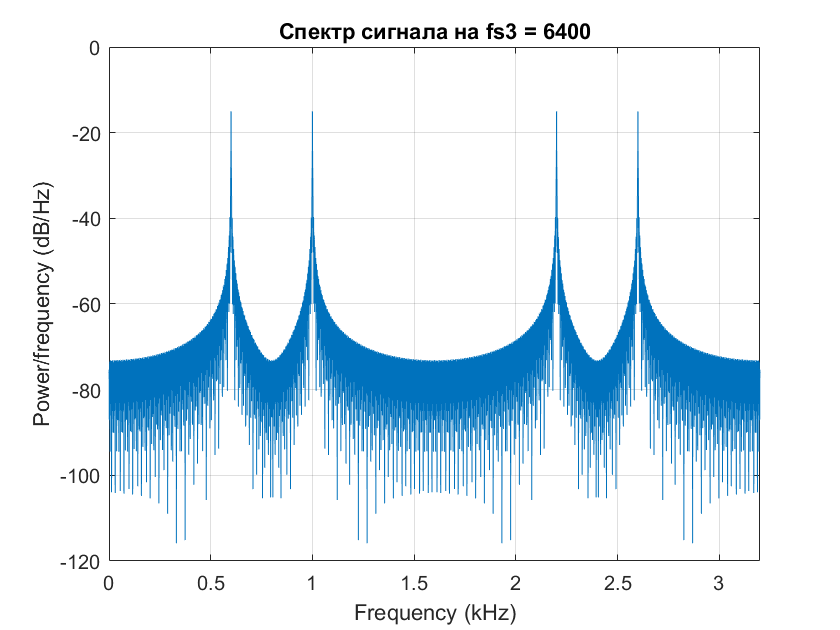

periodogram(x3,[],[],fs3);
title('Cпектр сигнала на fs3 = 6400');